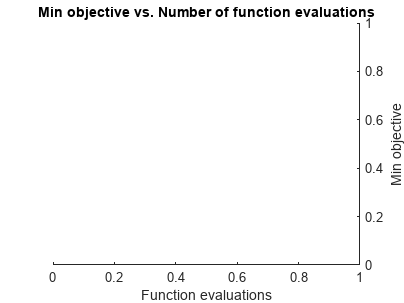

|===============================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | EncoderTrans-| DecoderTrans-|    MaxEpochs | L2WeightRegu-| SparsityProp-| SparsityRegu-|    ScaleData | InitialLearn-|
|      | result |             | runtime     | (observed)  | (estim.)    | ferFunction  | ferFunction  |              | larization   | ortion       | larization   |              | Rate         |
|===============================================================================================================================================================================================|
|    1 | Best   |         0.5 |      34.365 |         0.5 |         0.5 |       satlin |       logsig |            2 |       0.0498 |      0.31091 |     0.070955 |      0.34483 |      0.31699 |


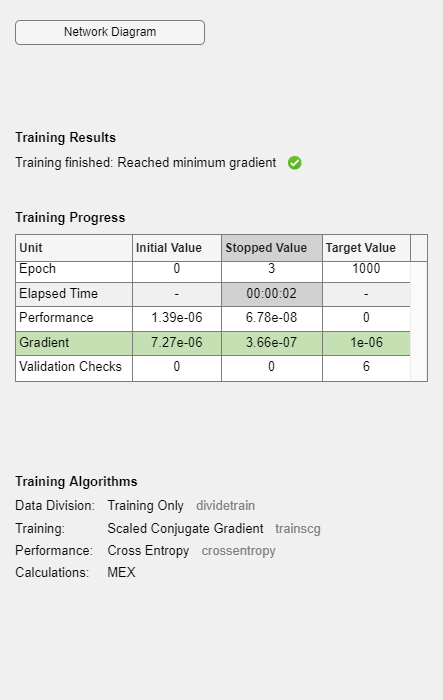

% balModes = ESPConst.BALANCE_MODES;
% for i=(1:length(balModes))
%     mode = balModes(i);
%     preprocessDatasets(true, mode);
% end
% 

% datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
% for i=1:length(datasets)
%     path = ESPConst.PATH_DATASET_PREPROCESSED + datasets(i).name;
%     [t, v] = prepareInput(path, ESPConst.RATIO_TRAIN, ESPConst.RATIO_VAL);
%     bayesOptimizationLSTM(t, v, datasets(i).name);
% end

datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(datasets)
    path = ESPConst.PATH_DATASET_PREPROCESSED + datasets(i).name;
    trainInput = load(path).data;
    bayesOptimizationAE(trainInput, datasets(i).name);
end